function lif_simulation()
    % Define default parameters
    pars = default_pars();

    % Example usage for LIF simulation
    pars = default_pars('T', 500); % Set simulation duration to 500 ms
    [v, sp] = run_LIF(pars, 100, true);
    plot_volt_trace(pars, v, sp);

    % Gaussian White Noise Example
    pars = default_pars('T', 1000);
    I_GWN1 = my_GWN(pars, 250, 0.5, 2020);
    I_GWN2 = my_GWN(pars, 250, 3.0, 2020);
    [~, sp1] = run_LIF(pars, I_GWN1);
    [~, sp2] = run_LIF(pars, I_GWN2);

    % Plot ISI histograms
    [isi1, cv1] = isi_cv_LIF(sp1);
    [isi2, cv2] = isi_cv_LIF(sp2);
    my_hists(isi1, isi2, cv1, cv2, 0.5, 3.0);
end

function pars = default_pars(varargin)
    % Default parameters for LIF model
    pars.V_th = -55;     % Spike threshold (mV)
    pars.V_reset = -75;  % Reset potential (mV)
    pars.tau_m = 10;     % Membrane time constant (ms)
    pars.g_L = 10;       % Leak conductance (nS)
    pars.V_init = -75;   % Initial potential (mV)
    pars.E_L = -75;      % Leak reversal potential (mV)
    pars.tref = 2;       % Refractory time (ms)
    pars.T = 400;        % Simulation duration (ms)
    pars.dt = 0.1;       % Simulation time step (ms)

    % Override parameters with varargin inputs
    for i = 1:2:length(varargin)
        pars.(varargin{i}) = varargin{i+1};
    end

    pars.range_t = 0:pars.dt:pars.T - pars.dt;
end

function [v, sp] = run_LIF(pars, Iinj, stop)
    if nargin < 3
        stop = false;
    end

    % Extract parameters
    V_th = pars.V_th; V_reset = pars.V_reset;
    tau_m = pars.tau_m; g_L = pars.g_L;
    V_init = pars.V_init; E_L = pars.E_L;
    dt = pars.dt; tref = pars.tref;
    range_t = pars.range_t;

    % Initialize variables
    v = zeros(size(range_t));
    v(1) = V_init;
    sp = [];
    tr = 0;

    % Set input current
    Iinj = Iinj .* ones(size(range_t));
    if stop
        Iinj(1:floor(end/2)-1000) = 0;
        Iinj(floor(end/2)+1000:end) = 0;
    end

    % Simulate LIF
    for t = 1:length(range_t) - 1
        if tr > 0
            v(t) = V_reset;
            tr = tr - 1;
        elseif v(t) >= V_th
            sp = [sp, t * dt];
            v(t) = V_reset;
            tr = tref / dt;
        end
        dv = (-(v(t) - E_L) + Iinj(t) / g_L) * (dt / tau_m);
        v(t + 1) = v(t) + dv;
    end
end

function plot_volt_trace(pars, v, sp)
    figure;
    plot(pars.range_t, v, 'b');
    hold on;
    yline(pars.V_th, '--k', 'Threshold');
    if ~isempty(sp)
        spike_idx = round(sp / pars.dt);
        v(spike_idx) = v(spike_idx) + 20; % Adjust spike heights
    end
    xlabel('Time (ms)');
    ylabel('Membrane Potential (mV)');
    ylim([-80, -40]);
    legend('Membrane potential', 'Threshold');
    hold off;
end

function I_GWN = my_GWN(pars, mu, sig, seed)
    if nargin < 4
        rng('shuffle');
    else
        rng(seed);
    end
    dt = pars.dt; range_t = pars.range_t;
    I_GWN = mu + sig * randn(size(range_t)) / sqrt(dt / 1000);
end

function my_hists(isi1, isi2, cv1, cv2, sigma1, sigma2)
    figure;
    edges = 10:2:30;
    subplot(1, 2, 1);
    histogram(isi1, edges, 'FaceColor', 'b', 'FaceAlpha', 0.5);
    xlabel('ISI (ms)');
    ylabel('Count');
    title(sprintf('\\sigma = %.1f, CV = %.3f', sigma1, cv1));

    subplot(1, 2, 2);
    histogram(isi2, edges, 'FaceColor', 'r', 'FaceAlpha', 0.5);
    xlabel('ISI (ms)');
    ylabel('Count');
    title(sprintf('\\sigma = %.1f, CV = %.3f', sigma2, cv2));
end

function [isi, cv] = isi_cv_LIF(spike_times)
    if length(spike_times) < 2
        isi = NaN;
        cv = NaN;
    else
        isi = diff(spike_times);
        cv = std(isi) / mean(isi);
    end
end

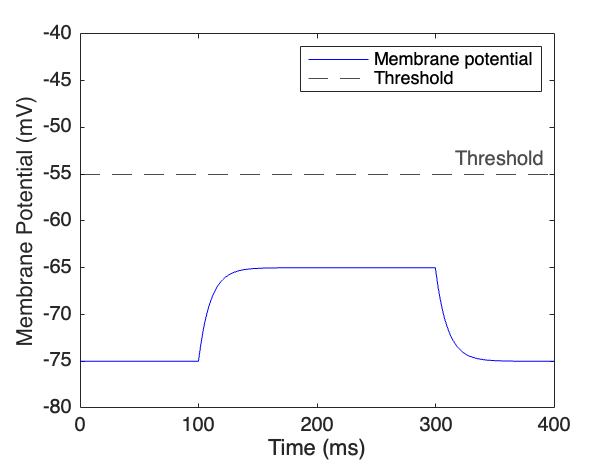

% Load default parameters
pars = default_pars();

% 1. Simulate the LIF model
% Equivalent to: v, sp = run_LIF(pars, Iinj=100, stop=True)
[v, sp] = run_LIF(pars, 100, true);

% Plot the membrane potential trace
% Equivalent to: plot_volt_trace(pars, v, sp)
plot_volt_trace(pars, v, sp);

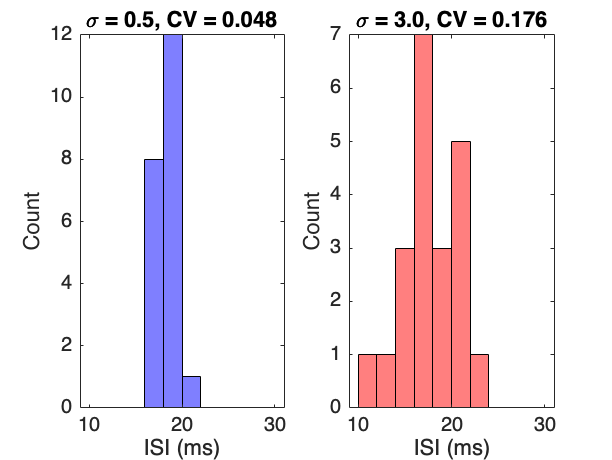


% 2. Generate Gaussian white noise input
% Equivalent to: I_GWN1 = my_GWN(pars, mu=250, sig=0.5, myseed=2020)
I_GWN1 = my_GWN(pars, 250, 0.5, 2020);

% Generate another Gaussian white noise input with a different sigma
% Equivalent to: I_GWN2 = my_GWN(pars, mu=250, sig=3.0, myseed=2020)
I_GWN2 = my_GWN(pars, 250, 3.0, 2020);

% Simulate the LIF model with Gaussian white noise
% Equivalent to: _, sp1 = run_LIF(pars, Iinj=I_GWN1)
[~, sp1] = run_LIF(pars, I_GWN1);

% Equivalent to: _, sp2 = run_LIF(pars, Iinj=I_GWN2)
[~, sp2] = run_LIF(pars, I_GWN2);

% 3. Compute inter-spike intervals and coefficients of variation
% Equivalent to: isi1, cv1 = isi_cv_LIF(sp1)
[isi1, cv1] = isi_cv_LIF(sp1);

% Equivalent to: isi2, cv2 = isi_cv_LIF(sp2)
[isi2, cv2] = isi_cv_LIF(sp2);

% 4. Plot histograms for the ISI and CV
% Equivalent to: my_hists(isi1, isi2, cv1, cv2, sig_gwn1, sig_gwn2)
my_hists(isi1, isi2, cv1, cv2, 0.5, 3.0);

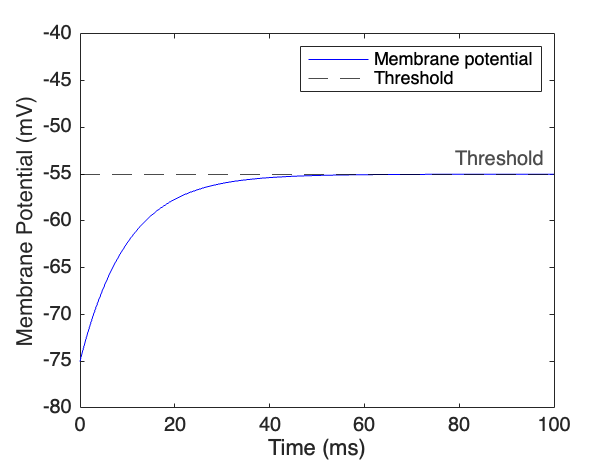


% 5. Simulate the effect of DC input on membrane potential
% Equivalent to: diff_DC(I_dc=200., tau_m=10.)
pars = default_pars('T', 100); % Adjust simulation duration for shorter example
[v, sp] = run_LIF(pars, 200); % Adjust DC input current
plot_volt_trace(pars, v, sp);

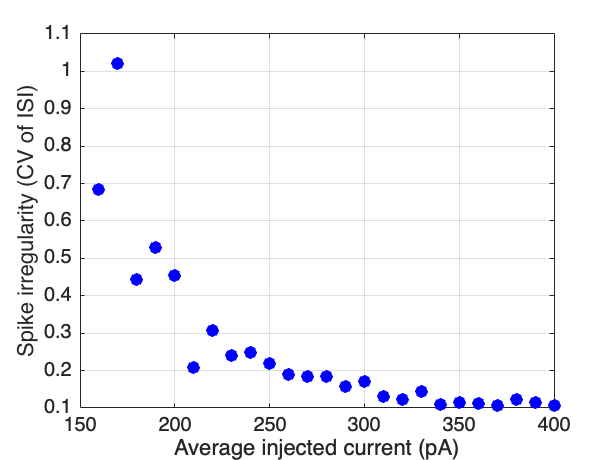


% 6. Analyze spike irregularity with varying GWN standard deviation
% Equivalent to: diff_std_affect_fI(sig_gwn=3.0)
sig_gwn = 3.0;
pars = default_pars('T', 1000); % Longer simulation for spike analysis
I_mean = 100:10:400; % Range of input means
spk_count = zeros(1, length(I_mean));
cv_isi = nan(1, length(I_mean));

for i = 1:length(I_mean)
    I_GWN = my_GWN(pars, I_mean(i), sig_gwn);
    [~, sp] = run_LIF(pars, I_GWN);
    spk_count(i) = length(sp);
    if length(sp) > 3
        isi = diff(sp);
        cv_isi(i) = std(isi) / mean(isi);
    end
end

% Plot F-I curve (irregularity vs input mean)
figure;
plot(I_mean(spk_count > 5), cv_isi(spk_count > 5), 'bo', 'MarkerFaceColor', 'b');
xlabel('Average injected current (pA)');
ylabel('Spike irregularity (CV of ISI)');
grid on;